**DIAGNOSIS OF PARKINSON'S DISEASE USING DYSPHONIA MEASUREMENTS**

Dataset used: [http://archive.ics.uci.edu/ml/machine-learning-databases/parkinsons/](http://archive.ics.uci.edu/ml/machine-learning-databases/parkinsons/)

Team Members: Aaditi Saoji (avsaoji), Rucha Apte (ruchaa)

**DATA EXPLORATION AND VISUALIZATION**

**Summary Statistics:**

- Mean

- Median 

- Range

**Plots:**

- Histogram

- Boxplots

- Scatter Plots (scatterhist)

- Pie Chart

**Statistical Analysis:**

- T-test

- Heatmaps

**Unsupervised:**

- PCA

- Hierarchical

- K-means Clustering

% Read the table
PD = readtable('parkinsons_data.csv');

% Display the first 10 records
head(PD,10)

ans = 10×24 table
           name           MDVP_Fo_Hz_    MDVP_Fhi_Hz_    MDVP_Flo_Hz_    MDVP_Jitter___    MDVP_Jitter_Abs_    MDVP_RAP    MDVP_PPQ    Jitter_DDP    MDVP_Shimmer    MDVP_Shimmer_dB_    Shimmer_APQ3    Shimmer_APQ5    MDVP_APQ    Shimmer_DDA      NHR       HNR      status     RPDE        DFA      spread1    spread2      D2        PPE  
    __________________    ___________    ____________    ____________    ______________    ________________    ________

% Report size of PD dataset
size_PD = size(PD)

size_PD =    195    24


% Excluding the 'Name' column
PD_new = PD(:,(2:24));

**Summary Statistics:**

**Method 1: Mean, Median, Range**

% Excluding the 'Name' and 'Status' column
data_table = PD(:,[2:17,19:end]);

stat = PD.status;

% Convert data to array
data = table2array(data_table);

% Names of features except for 'Name' and 'Status' column
data_names = PD.Properties.VariableNames([2:17,19:end]);

% Calculating mean of all features
mean_feat = mean(data);

% Calculating median of all features
median_feat = median(data);

% Calculating max, min and range of all features
max_feat = max(data);
min_feat = min(data);
range_feat = max_feat - min_feat;

t = table(data_names', mean_feat', median_feat', max_feat', min_feat', range_feat');
t.Properties.VariableNames = {'Variable Names' 'Mean' 'Median' 'Maximum' 'Minimum' 'Range'};
display(t)

t = 22×6 table
       Variable Names          Mean       Median     Maximum    Minimum     Range  
    ____________________    __________    _______    _______    _______    ________

    {'MDVP_Fo_Hz_'     }        154.23     148.79     260.11     88.333      171.77
    {'MDVP_Fhi_Hz_'    }         197.1     175.83     592.03     102.14      489.88
    {'MDVP_Flo_Hz_'    }        116.32     104.31     239.17     65.476      173.69
    {'MDVP_Jitter___'  }     0.0062205    0.00494    0.03316    0.00168     0.03148
    {'MDVP_Jitter_Abs_'}    4.3959e-05      3e-05    0.00026      7e-06    0.000253
    {'MDVP_RAP'        }     0.0033064     0.0025    0.02144    0.00068     0.02076
    {'MDVP_PPQ'        }     0.0034464    0.00269    0.01958    0.00092     0.01866
    {'Jitter_DDP'      }

**Plots:**

**Method 1: Histogram**

Histograms are used to look at the distribution of continuous data. 

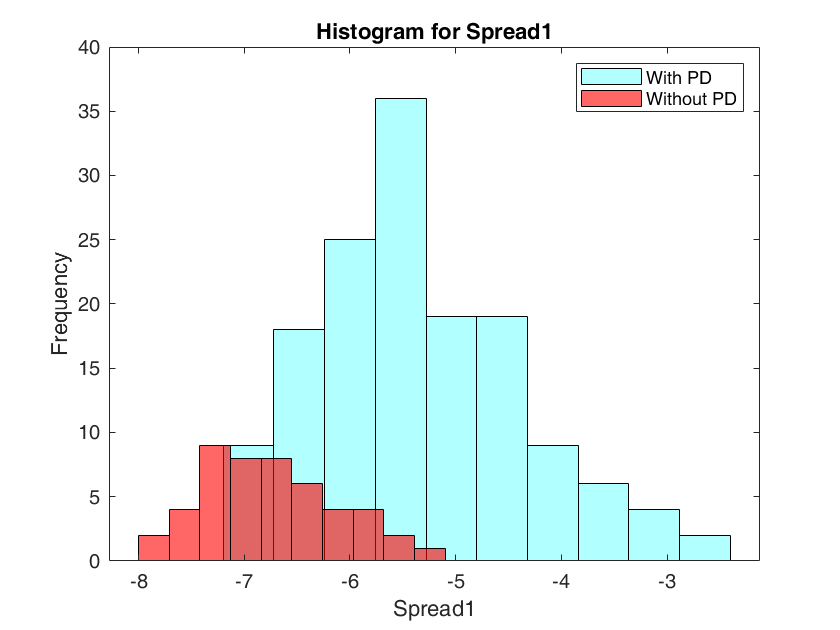

figure(1)

status0_spread1 = PD.spread1(PD.status==0);
status1_spread1 = PD.spread1(PD.status==1);

% Plotting Histogram of Spread1 wrt Status0 and Status1 on the same plot for comparison
Spread1_histogram_status1 = histogram(status1_spread1,'FaceAlpha',0.3);
Spread1_histogram_status1.NumBins = 10;
Spread1_histogram_status1.FaceColor = 'cyan';

hold on

Spread1_histogram_status0 = histogram(status0_spread1);
Spread1_histogram_status0.NumBins = 10;
Spread1_histogram_status0.FaceColor = 'red';

xlabel("Spread1");
ylabel("Frequency");
legend('With PD','Without PD');
title('Histogram for Spread1');

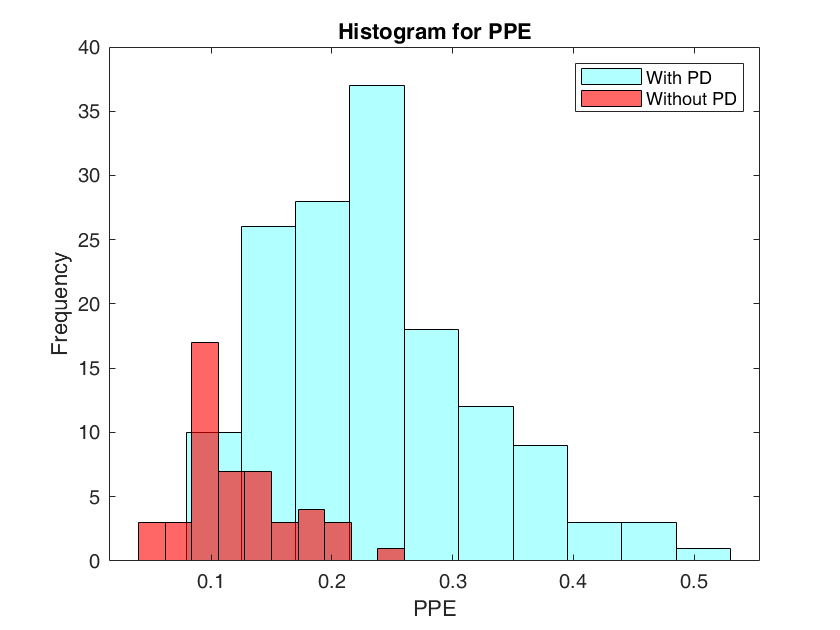

figure(2)
status0_PPE = PD.PPE(PD.status==0);
status1_PPE = PD.PPE(PD.status==1);

% Plotting Histogram of PPE wrt Status0 and Status1 on the same plot for comparison
PPE_histogram_status1 = histogram(status1_PPE,'FaceAlpha',0.3);
PPE_histogram_status1.NumBins = 10;
PPE_histogram_status1.FaceColor = 'cyan';

hold on

PPE_histogram_status0 = histogram(status0_PPE);
PPE_histogram_status0.NumBins = 10;
PPE_histogram_status0.FaceColor = 'red';

xlabel("PPE");
ylabel("Frequency");
legend('With PD','Without PD');
title('Histogram for PPE');

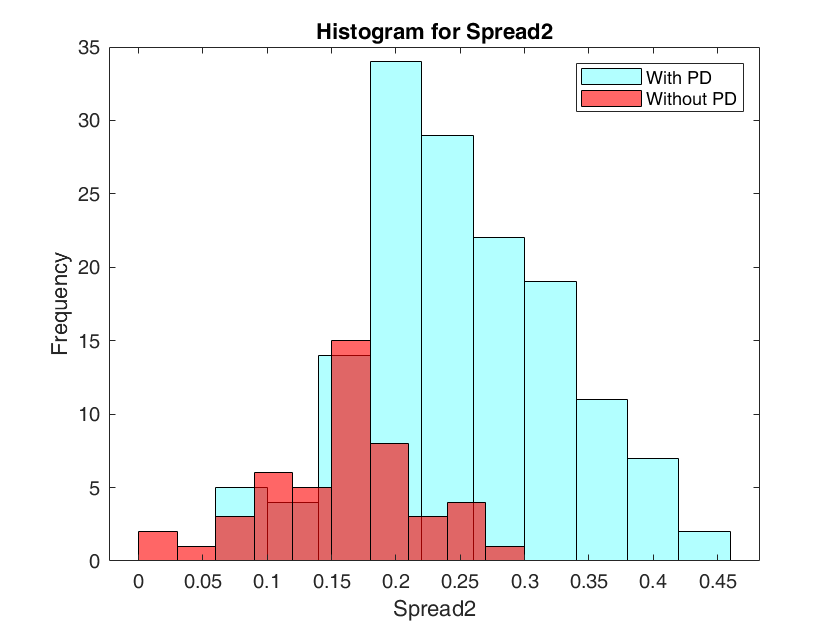

figure(3)
status0_spread2 = PD.spread2(PD.status==0);
status1_spread2 = PD.spread2(PD.status==1);

% Plotting Histogram of Spread2 wrt Status0 and Status1 on the same plot for comparison
Spread2_histogram_status1 = histogram(status1_spread2,'FaceAlpha',0.3);
Spread2_histogram_status1.NumBins = 10;
Spread2_histogram_status1.FaceColor = 'cyan';

hold on

Spread2_histogram_status0 = histogram(status0_spread2);
Spread2_histogram_status0.NumBins = 10;
Spread2_histogram_status0.FaceColor = 'red';

xlabel("Spread2");
ylabel("Frequency");
legend('With PD','Without PD');
title('Histogram for Spread2');

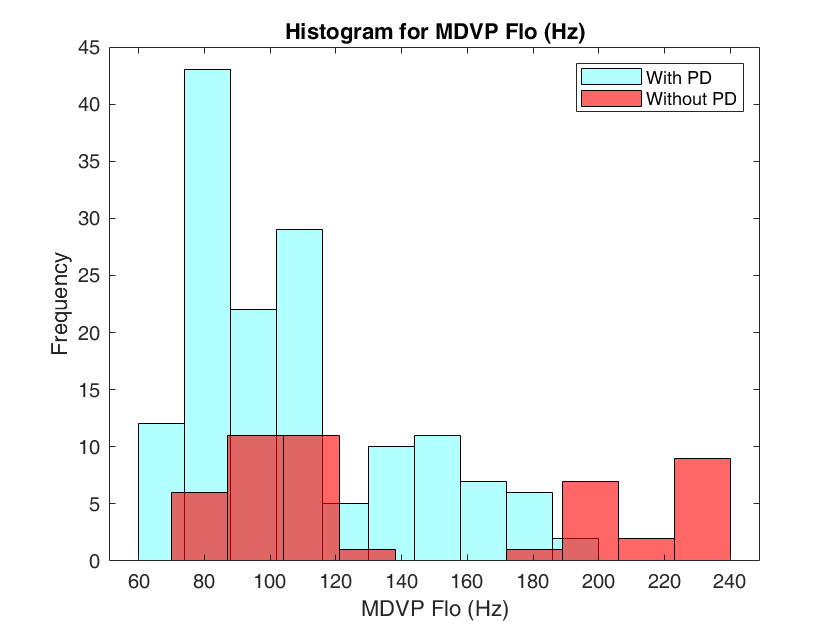

figure(4)
status0_MDVP_Flo_Hz_ = PD.MDVP_Flo_Hz_(PD.status==0);
status1_MDVP_Flo_Hz_ = PD.MDVP_Flo_Hz_(PD.status==1);

% Plotting Histogram of MDVP_Flo wrt Status0 and Status1 on the same plot for comparison
MDVPFlo_histogram_status1 = histogram(status1_MDVP_Flo_Hz_,'FaceAlpha',0.3);
MDVPFlo_histogram_status1.NumBins = 10;
MDVPFlo_histogram_status1.FaceColor = 'cyan';

hold on

MDVPFlo_histogram_status0 = histogram(status0_MDVP_Flo_Hz_);
MDVPFlo_histogram_status0.NumBins = 10;
MDVPFlo_histogram_status0.FaceColor = 'red';

xlabel("MDVP Flo (Hz)");
ylabel('Frequency')
legend('With PD','Without PD');
title('Histogram for MDVP Flo (Hz)');

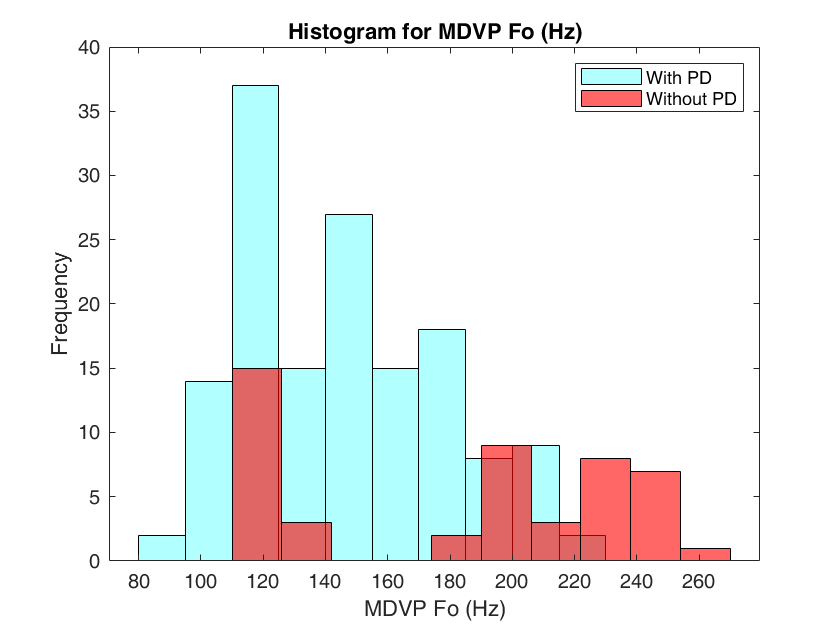

figure(5)
status0_MDVP_Fo_Hz_ = PD.MDVP_Fo_Hz_(PD.status==0);
status1_MDVP_Fo_Hz_ = PD.MDVP_Fo_Hz_(PD.status==1);

% Plotting Histogram of MDVP_Fo wrt Status0 and Status1 on the same plot for comparison
MDVPFo_histogram_status1 = histogram(status1_MDVP_Fo_Hz_,'FaceAlpha',0.3);
MDVPFo_histogram_status1.NumBins = 10;
MDVPFo_histogram_status1.FaceColor = 'cyan';

hold on

MDVPFo_histogram_status0 = histogram(status0_MDVP_Fo_Hz_);
MDVPFo_histogram_status0.NumBins = 10;
MDVPFo_histogram_status0.FaceColor = 'red';

xlabel("MDVP Fo (Hz)");
ylabel("Frequency");
legend('With PD','Without PD');
title('Histogram for MDVP Fo (Hz)');

**Method 2: Boxplots**

Boxplots are also helpful for looking at data distribution. In addition to showing the shape of the distribution, boxplots display the median value, the interquartile range, minimum/maxmimum values, and outlier points.

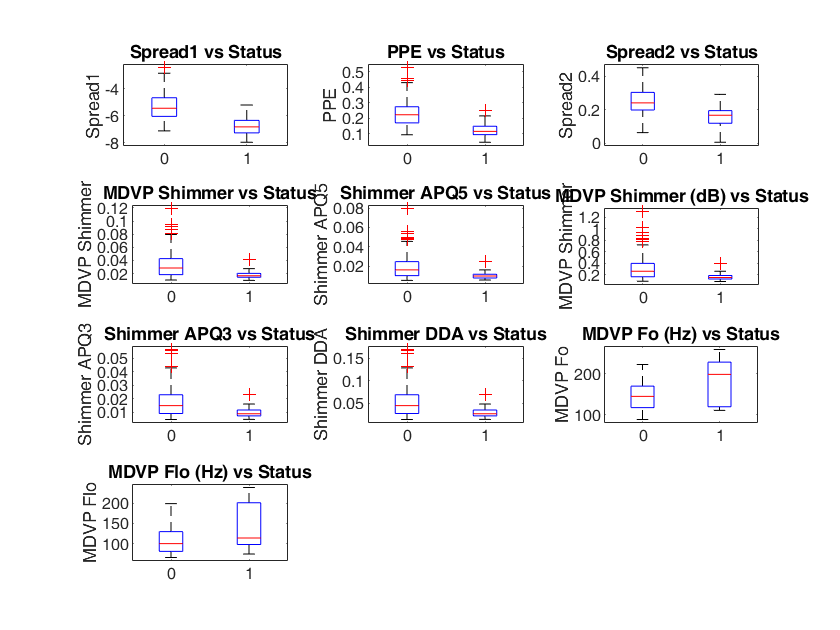

figure;
subplot(4,3,1)
boxplot(PD.spread1,PD.status==0);
ylabel('Spread1')
title('Spread1 vs Status');

subplot(4,3,2)
boxplot(PD.PPE,PD.status==0);
ylabel('PPE')
title('PPE vs Status');

subplot(4,3,3)
boxplot(PD.spread2,PD.status==0);
ylabel('Spread2')
title('Spread2 vs Status');

subplot(4,3,4)
boxplot(PD.MDVP_Shimmer,PD.status==0);
ylabel('MDVP Shimmer')
title('MDVP Shimmer vs Status');

subplot(4,3,5)
boxplot(PD.Shimmer_APQ5,PD.status==0);
ylabel('Shimmer APQ5')
title('Shimmer APQ5 vs Status');

subplot(4,3,6)
boxplot(PD.MDVP_Shimmer_dB_,PD.status==0);
ylabel('MDVP Shimmer')
title('MDVP Shimmer (dB) vs Status');

subplot(4,3,7)
boxplot(PD.Shimmer_APQ3,PD.status==0);
ylabel('Shimmer APQ3')
title('Shimmer APQ3 vs Status');

subplot(4,3,8)
boxplot(PD.Shimmer_DDA,PD.status==0);
ylabel('Shimmer DDA')
title('Shimmer DDA vs Status');

subplot(4,3,9)
boxplot(PD.MDVP_Fo_Hz_,PD.status==0);
ylabel('MDVP Fo')
title('MDVP Fo (Hz) vs Status');

subplot(4,3,10)
boxplot(PD.MDVP_Flo_Hz_,PD.status==0);
ylabel('MDVP Flo')
title('MDVP Flo (Hz) vs Status');

**Method 3: Scatter Plots (scatterhist)**

Creates a 2D scatter plot of the data and displays marginal distribution of the two vectors as histograms on horizontal and vertical axes of the plot.

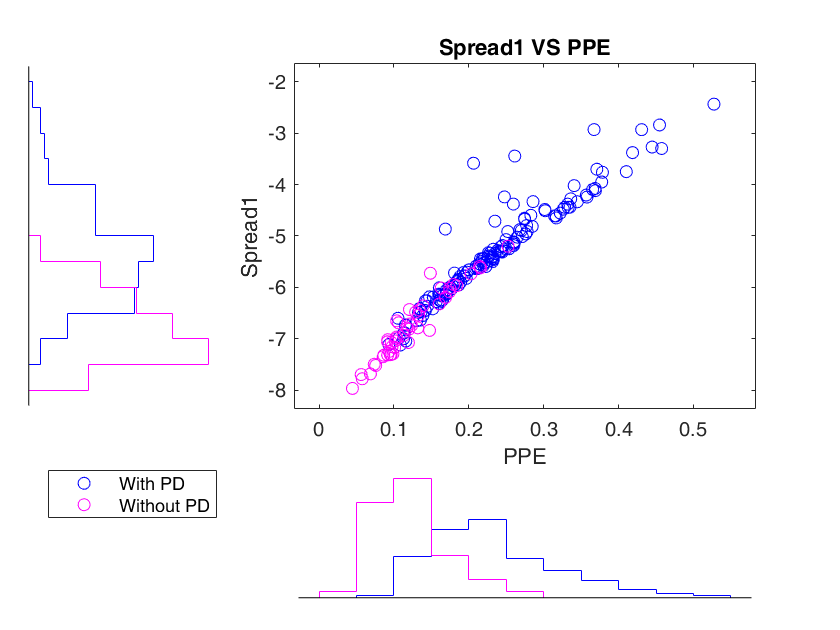

figure;
scatterhist(PD.PPE,PD.spread1,'Group',PD.status==0,'Color','bm');
xlabel('PPE')
ylabel('Spread1')
legend('With PD','Without PD')
title('Spread1 VS PPE')

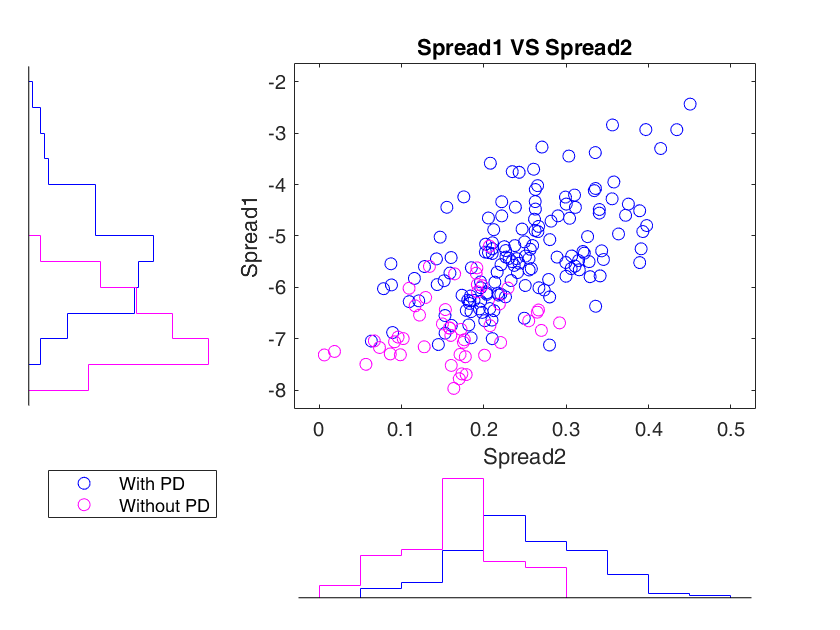

figure;
scatterhist(PD.spread2,PD.spread1,'Group',PD.status==0,'Color','bm');
xlabel('Spread2')
ylabel('Spread1')
legend('With PD','Without PD')
title('Spread1 VS Spread2')

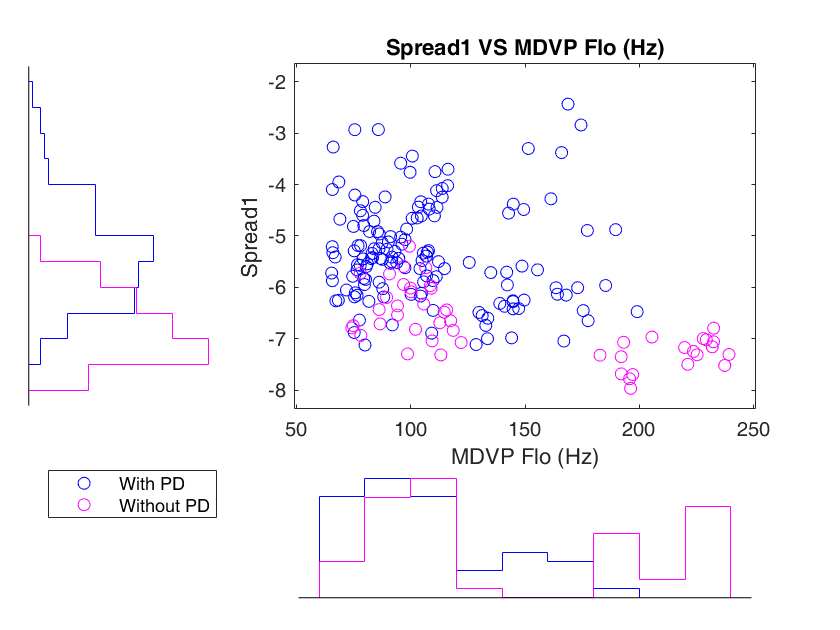

figure;
scatterhist(PD.MDVP_Flo_Hz_,PD.spread1,'Group',PD.status==0,'Color','bm');
xlabel('MDVP Flo (Hz)')
ylabel('Spread1')
legend('With PD','Without PD')
title('Spread1 VS MDVP Flo (Hz)')

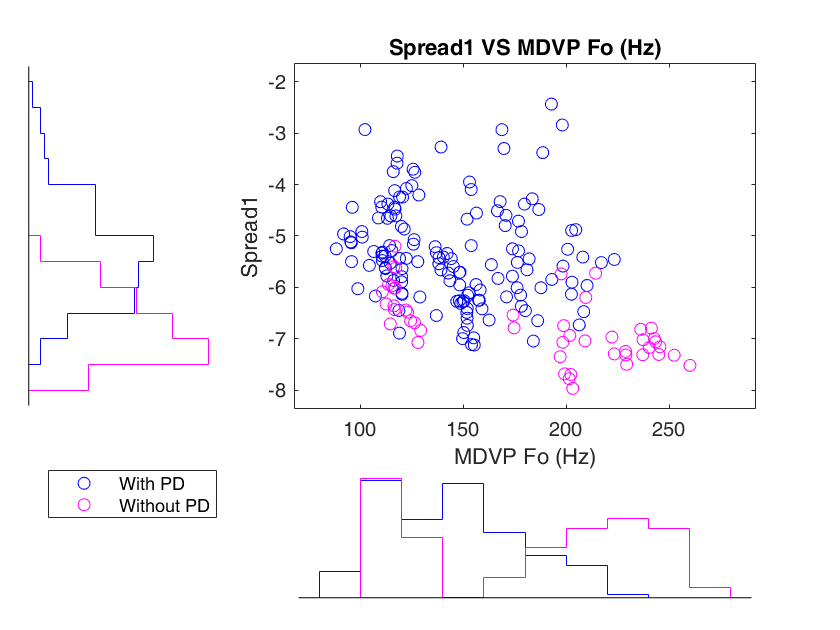

figure;
scatterhist(PD.MDVP_Fo_Hz_,PD.spread1,'Group',PD.status==0,'Color','bm');
xlabel('MDVP Fo (Hz)')
ylabel('Spread1')
legend('With PD','Without PD')
title('Spread1 VS MDVP Fo (Hz)')

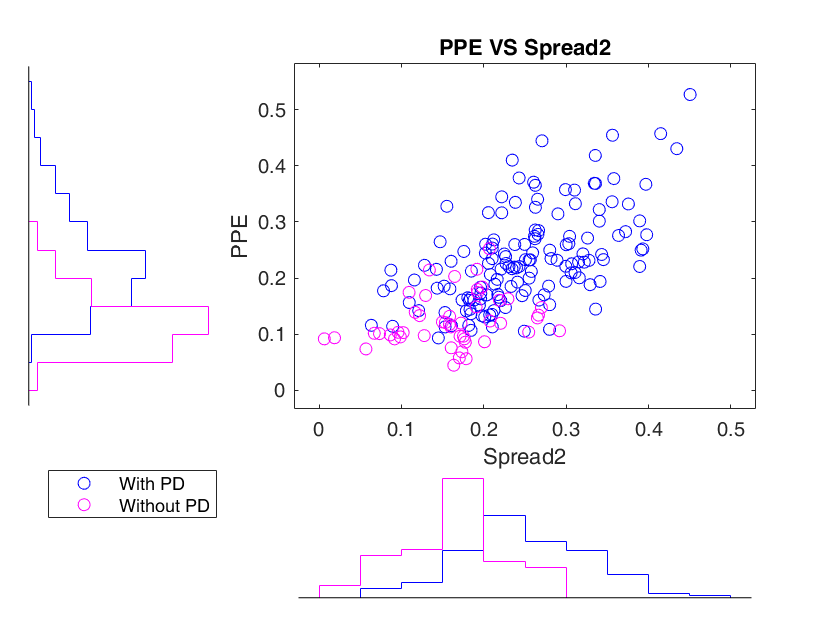

figure;
scatterhist(PD.spread2,PD.PPE,'Group',PD.status==0,'Color','bm');
xlabel('Spread2')
ylabel('PPE')
legend('With PD','Without PD')
title('PPE VS Spread2')

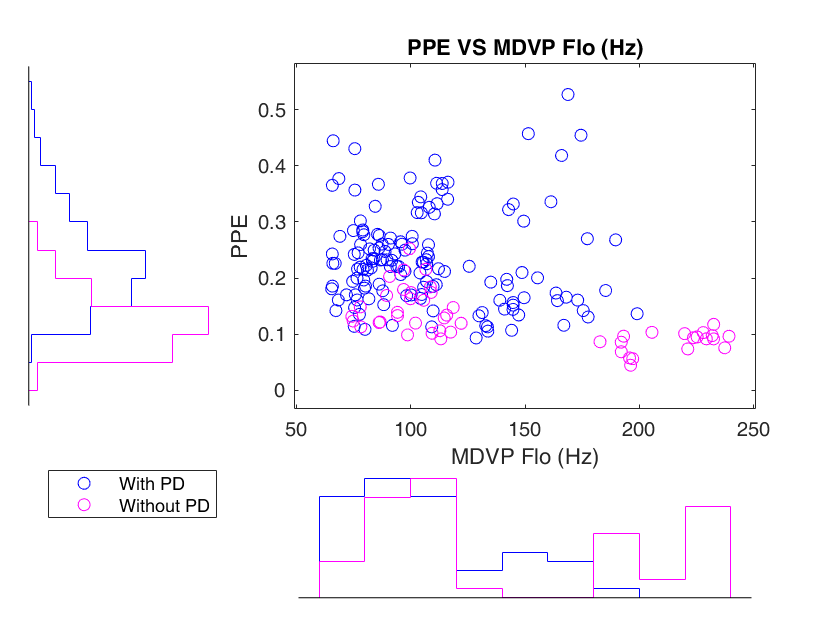

figure;
scatterhist(PD.MDVP_Flo_Hz_,PD.PPE,'Group',PD.status==0,'Color','bm');
xlabel('MDVP Flo (Hz)')
ylabel('PPE')
legend('With PD','Without PD')
title('PPE VS MDVP Flo (Hz)')

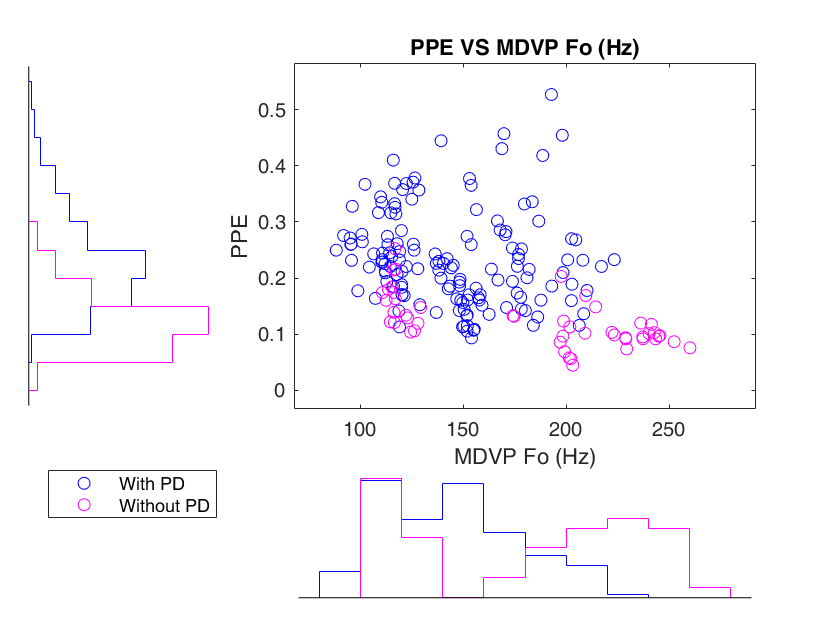

figure;
scatterhist(PD.MDVP_Fo_Hz_,PD.PPE,'Group',PD.status==0,'Color','bm');
xlabel('MDVP Fo (Hz)')
ylabel('PPE')
legend('With PD','Without PD')
title('PPE VS MDVP Fo (Hz)')

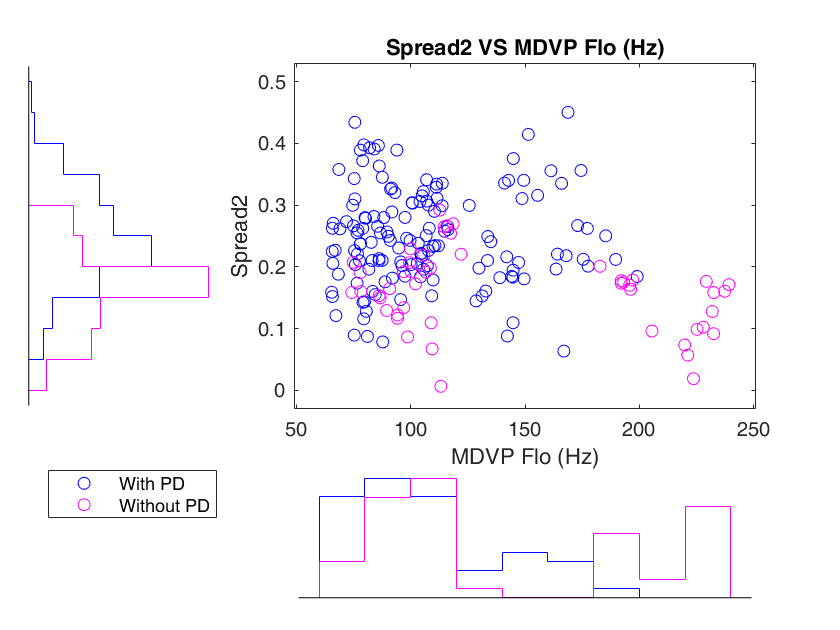

figure;
scatterhist(PD.MDVP_Flo_Hz_,PD.spread2,'Group',PD.status==0,'Color','bm');
xlabel('MDVP Flo (Hz)')
ylabel('Spread2')
legend('With PD','Without PD')
title('Spread2 VS MDVP Flo (Hz)')

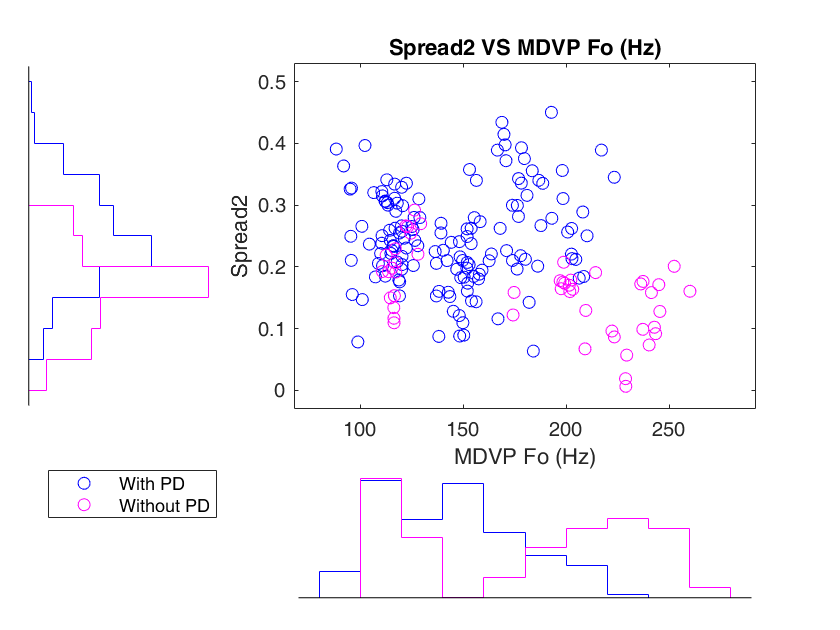

figure;
scatterhist(PD.MDVP_Fo_Hz_,PD.spread2,'Group',PD.status==0,'Color','bm');
xlabel('MDVP Fo (Hz)')
ylabel('Spread2')
legend('With PD','Without PD')
title('Spread2 VS MDVP Fo (Hz)')

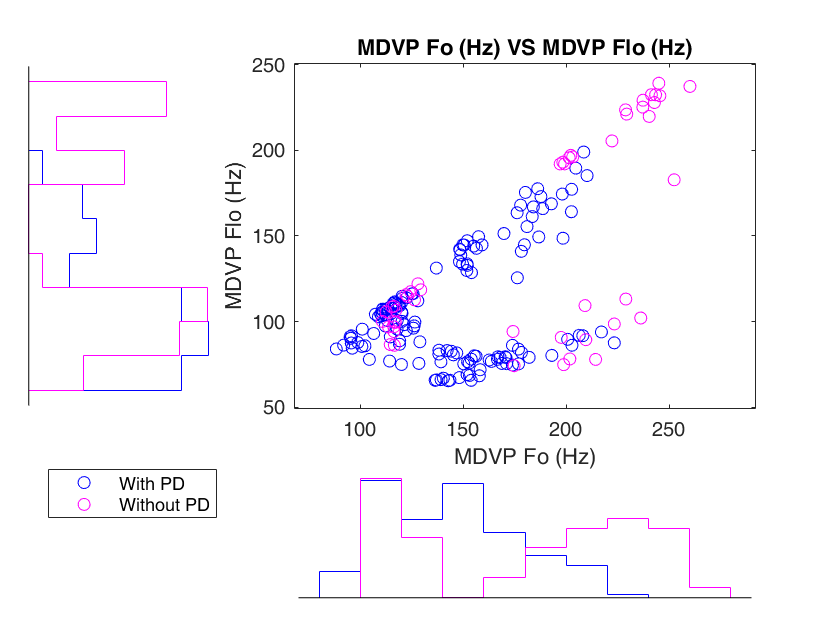

figure;
scatterhist(PD.MDVP_Fo_Hz_,PD.MDVP_Flo_Hz_,'Group',PD.status==0,'Color','bm');
xlabel('MDVP Fo (Hz)')
ylabel('MDVP Flo (Hz)')
legend('With PD','Without PD')
title('MDVP Fo (Hz) VS MDVP Flo (Hz)')

**Method 4: Pie Chart**

A pie- chart is a circular statistical graphic, which is divided into slices to illustrate numerical proportion.

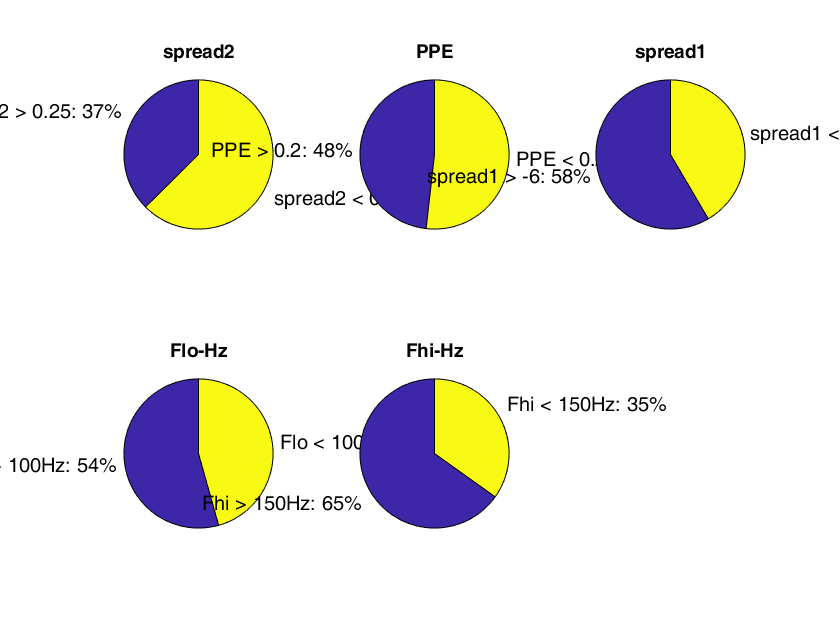

% spread2
figure()
subplot(2,3,1)
p1 = pie([sum(PD.spread2 > 0.25) sum(PD.spread2 < 0.25)]);
p1Text = findobj(p1,'Type','text');
percentValues1 = get(p1Text,'String'); 
txt1 = {'spread2 > 0.25: ';'spread2 < 0.25: '}; 
combinedtxt1 = strcat(txt1,percentValues1);
p1Text(1).String = combinedtxt1(1);
p1Text(2).String = combinedtxt1(2);
title('spread2');

% PPE
subplot(2,3,2)
p2 = pie([sum(PD.PPE > 0.2) sum(PD.PPE < 0.2)]);
p2Text = findobj(p2,'Type','text');
percentValues2 = get(p2Text,'String'); 
txt2 = {'PPE > 0.2: ';'PPE < 0.2: '}; 
combinedtxt2 = strcat(txt2,percentValues2);
p2Text(1).String = combinedtxt2(1);
p2Text(2).String = combinedtxt2(2);
title('PPE');

% spread1
subplot(2,3,3)
p3 = pie([sum(PD.spread1 > -6) sum(PD.spread1 < -6)]);
p3Text = findobj(p3,'Type','text');
percentValues3 = get(p3Text,'String'); 
txt3 = {'spread1 > -6: ';'spread1 < -6: '}; 
combinedtxt3 = strcat(txt3,percentValues3);
p3Text(1).String = combinedtxt3(1);
p3Text(2).String = combinedtxt3(2);
title('spread1');

% Flo_Hz
subplot(2,3,4)
p4 = pie([sum(PD.MDVP_Flo_Hz_ > 100) sum(PD.MDVP_Flo_Hz_ < 100)]);
p4Text = findobj(p4,'Type','text');
percentValues4 = get(p4Text,'String'); 
txt4 = {'Flo > 100Hz: ';'Flo < 100Hz: '}; 
combinedtxt4 = strcat(txt4,percentValues4);
p4Text(1).String = combinedtxt4(1);
p4Text(2).String = combinedtxt4(2);
title('Flo-Hz');

% Fhi_Hz
subplot(2,3,5)
p5 = pie([sum(PD.MDVP_Fhi_Hz_ > 150) sum(PD.MDVP_Fhi_Hz_ < 150)]);
p5Text = findobj(p5,'Type','text');
percentValues5 = get(p5Text,'String'); 
txt5 = {'Fhi > 150Hz: ';'Fhi < 150Hz: '}; 
combinedtxt5 = strcat(txt5,percentValues5);
p5Text(1).String = combinedtxt5(1);
p5Text(2).String = combinedtxt5(2);
title('Fhi-Hz');

**Statistical Analysis:**

**Method 1: T-test**

h_ttest = zeros(1,22);
p_ttest = zeros(1,22);
p_rank = zeros(1,22);
h_rank = zeros(1,22);

for i = 1:22
    [h_ttest(i), p_ttest(i)] = ttest2(data_table.(i)(PD.status == 0), data_table.(i)(PD.status == 1));
    [p_rank(i), h_rank(i)] = ranksum(data_table.(i)(PD.status == 0), data_table.(i)(PD.status == 1));
end
% Create table with h and p-values for two test types
t = splitvars(table([h_ttest', p_ttest', h_rank', p_rank']));
t.Properties.VariableNames = {'h_ttest', 'p_ttest', 'h_rank', 'p_rank'};
t.Properties.RowNames = data_names

t = 22×4 table
                        h_ttest     p_ttest      h_rank      p_rank  
                        _______    __________    ______    __________

    MDVP_Fo_Hz_            1       3.1219e-08      1       3.0515e-05
    MDVP_Fhi_Hz_           1         0.020276      1       0.00027963
    MDVP_Flo_Hz_           1        4.197e-08      1       4.1513e-05
    MDVP_Jitter___         1         8.21e-05      1       7.8979e-09
    MDVP_Jitter_Abs_       1       1.2823e-06      1       1.2757e-09
    MDVP_RAP               1       0.00016434      1       8.6894e-09
    MDVP_PPQ               1       4.2578e-05      1       2.4015e-09
    Jitter_DDP             1       0.00016455      1       8.1801e-09
    

According to both the tests, all the features meet the threshold p-value of 0.05 and thus reject the null hypothesis. Thus, all the selected 22 features have significant importance in classification of PD.

**Method 2: Heatmap**

Heatmap is a graphical representation of the correlation between the features using different colourshades. It maes it easy to visualize the complex data nad nderstand it at a glance,

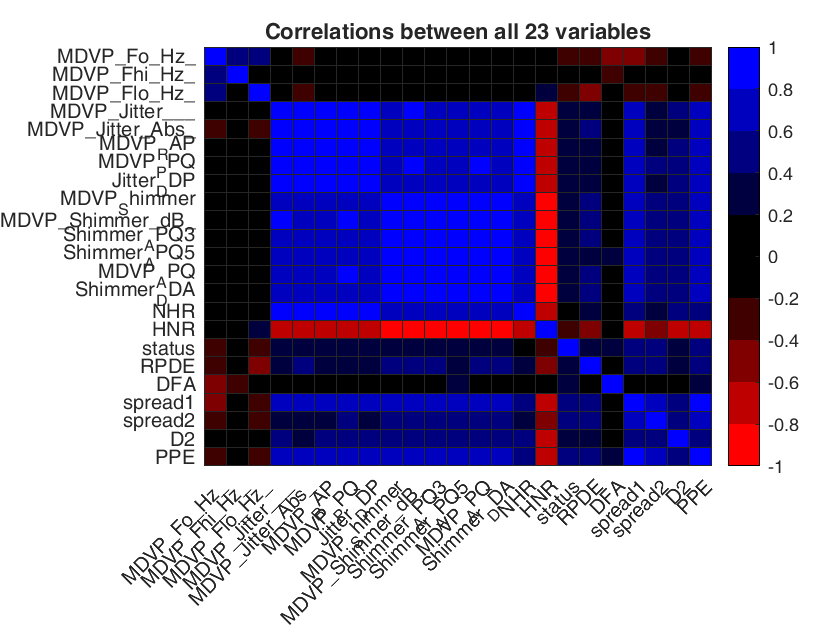

% Pearson's correlation
allcorr = corr(PD_new.Variables,"Rows","Complete");
figure()
h = heatmap(allcorr);
caxis([-1 1]);
red = linspace(1,0,5)';
blue = linspace(0,1,5)';
colormap([red zeros(5,1) zeros(5,1); zeros(5,1) zeros(5,1) blue]);
h.YDisplayLabels = PD_new.Properties.VariableNames;
h.XDisplayLabels = PD_new.Properties.VariableNames;
title('Correlations between all 23 variables');

**Unsupervised:**

**Method 1: Principal Component Analysis**

Principal Component Analysis is an analysis technique for feature extraction- it combines input variables in a specific way, in which it drops the *least important* variables while still retaining the most valuable parts of the variables.

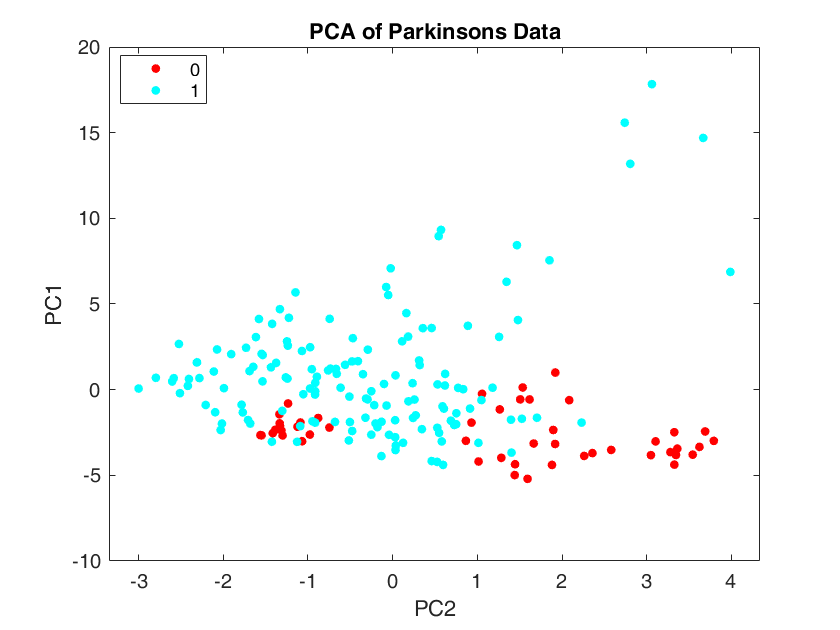

% Normalize the data
norm_data = zscore(data);

%Applying PCA on normalized data
[P,Y,~,~,var_explained] = pca(norm_data);

% Scatterplot of principal component scores
figure()
gscatter(Y(:,2), Y(:,1), stat)
xlabel('PC2');
ylabel('PC1');
title('PCA of Parkinsons Data');

**It can be seen from the plot that PC2 is the best amongst all principal components to segregate the data. (Tried plotting upto first 4 PCs, however found PC2 as the best one amongst them.)**

% Table for feature selection having highest values for PC2
PC2 = P(:,2);
t = table(data_names',PC2);
t = sortrows(t,'PC2','descend')

t = 22×2 table
            Var1              PC2   
    ____________________    ________

    {'MDVP_Fo_Hz_'     }      0.5534
    {'MDVP_Flo_Hz_'    }     0.39548
    {'MDVP_Fhi_Hz_'    }     0.34878
    {'NHR'             }     0.17054
    {'D2'              }     0.13281
    {'Jitter_DDP'      }     0.11605
    {'MDVP_RAP'        }     0.11604
    {'MDVP_Jitter___'  }    0.081789
    {'MDVP_Shimmer_dB_'}    0.076269
    {'MDVP_PPQ'        }    0.068102
    {'Shimmer_DDA'     }    0.058916
    {'Shimmer_APQ3'    }    0.058915
    {'MDVP_Shimmer'    }    0.052556
    {'Shimmer_APQ5'    }    0.050085
    {'MDVP_APQ'        }    0.047763
    {'HNR'             }    -0.03707


**It can be seen from the table that the features having maximum significance are:**

**1) MDVP_Fo_Hz_ (0.5534)**

**2) MDVP_Flo_Hz_ (0.3955)**

**3) MDVP_Fhi_Hz_ (0.3488)**

**4) DFA (-0.3108)**

**5) RPDE (-0.2486)**

**6) spread1 (-0.2393)**

**7) PPE (-0.2140)**

**8) spread2 (-0.2042)**

**Method 2: Hierarchical**

The clustergram performs hierarchical clustering analysis on the data and then generates clustergram based on the analysis along with a dendrogram and heatmap.s

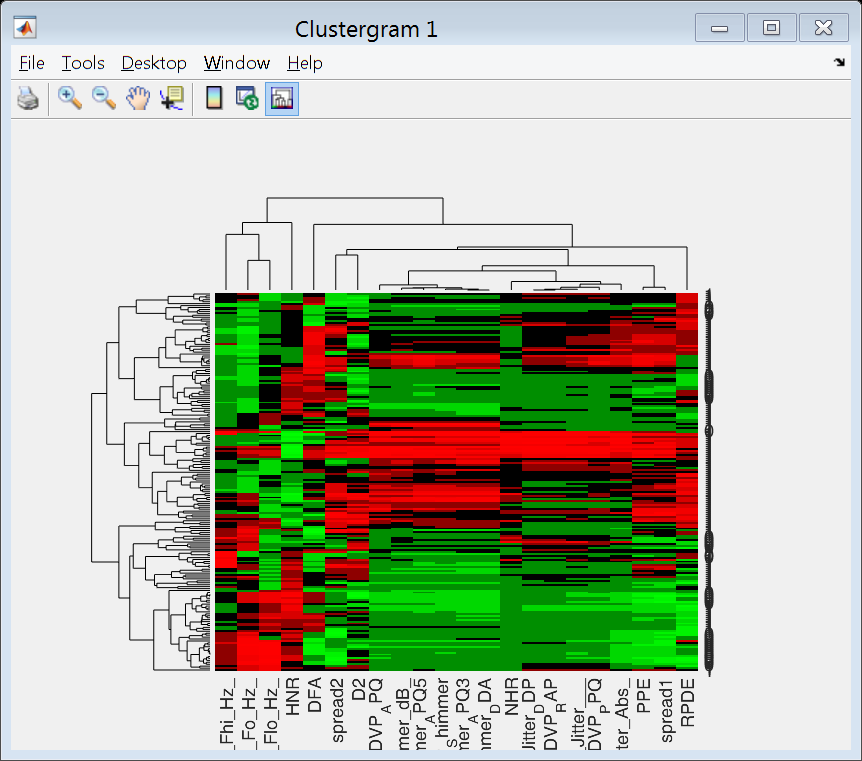

cg_corr = clustergram(norm_data,'RowLabels',stat,'ColumnLabels', data_names,'standardize', ...
    'column','RowPDist','correlation','ColumnPDist','correlation');

**Method 3: K-means Clustering**

It deals with unlabeled data in which it aims to partition the n observations into k clusters in wherein each observation belongs to the cluster with the nearest mean.

j = 1;
for i = 2:10
    idx = kmeans(data,i);
    s = silhouette(data,idx);
    s_score(j) = mean(s);
    j = j+1;
end

cluster_groups = (2:10)';
scores = s_score';
t_cluster = table(cluster_groups, scores);
t_cluster = sortrows(t_cluster,'scores','descend')

t_cluster = 9×2 table
    cluster_groups    scores 
    ______________    _______

           2          0.88372
           7          0.71253
          10          0.70768
           4          0.70122
           3           0.6981
           6          0.69483
           5          0.67908
           8          0.64306
           9          0.63735


From the above table, it can be seen that the **optimal number of clusters is 2**. The silhoutte analysis shows that k = 2 has the highest score of 0.8837.

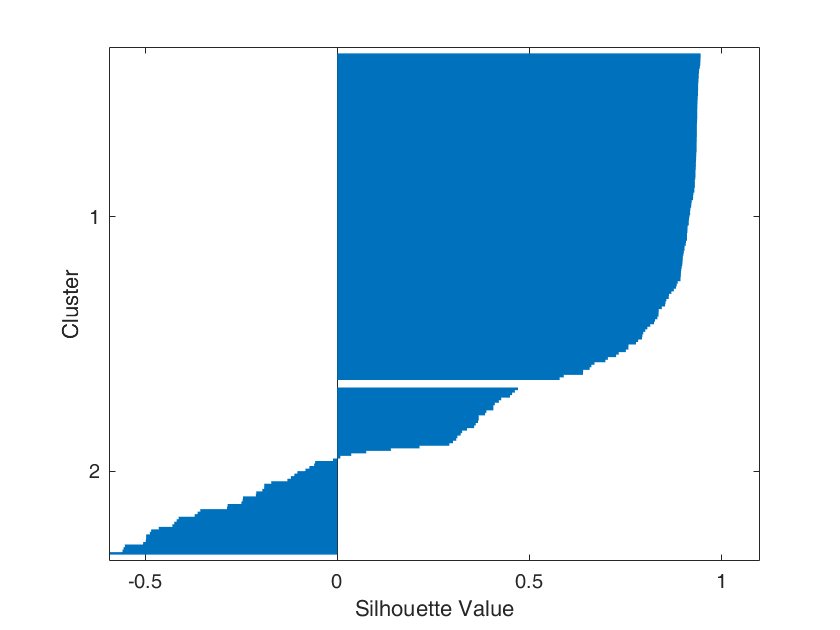

% Plotting silhoutte score for number of clusters = 2
idx = kmeans(data,2);
silhouette(data,idx)

% Cluster of people suffering from PD (status = 1)
cluster1 = PD.status(idx == 1)

cluster1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


accuracy_cluster1 = sum(cluster1 == 1)/length(cluster1)

accuracy_cluster1 = 0.8760

% Cluster of people not suffering from PD (status = 0)
cluster2 = PD.status(idx == 2)

cluster2 =      1
     0
     0
     0
     0
     0
     0
     1
     1
     1


accuracy_cluster2 = sum(cluster2 == 0)/length(cluster2)

accuracy_cluster2 = 0.4848

**ML ALGORITHMS:**

- Random Guess

- Logistic Regression

- Decision Trees

- Random Forest

- Support Vector Machines

- Neural Network with Logistic Regression  (Bonus)

- Shallow Neural Network (Bonus)

**RANDOM GUESS**

% Excluding columns 'Name' and 'Status'
X = data;
Y = stat;

[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X,Y,0.7);

accuracy_randomGuess = zeros(100,1);
precision_randomGuess = zeros(100,1);
recall_randomGuess = zeros(100,1);
for i = 1:100
    % Creating a vector of random predictions of 1 and 0s
    random_pred = Ytrain(randperm(length(Ytest)));
    accuracy_randomGuess(i,1) = sum(random_pred == Ytest)/length(Ytest);
    precision_randomGuess(i,1) = sum(random_pred==1 & Ytest==1)/sum(random_pred);
    recall_randomGuess(i,1) = sum(random_pred==1 & Ytest==1)/sum(Ytest);
end
% Mean Accuracy
mean_accuracy_randomGuess = mean(accuracy_randomGuess)

mean_accuracy_randomGuess = 0.6379

% Mean Precision
mean_precision_randomGuess = mean(precision_randomGuess)

mean_precision_randomGuess = 0.7907

% Mean Recall
mean_recall_randomGuess = mean(recall_randomGuess)

mean_recall_randomGuess = 0.7391

**LOGISTIC REGRESSION**

% Three-fold cross validation
index = crossvalind('kfold',size(Xtrain,1),3);
accuracy_log_reg = zeros(3,1);
precision_log_reg = zeros(3,1);
recall_log_reg = zeros(3,1);
MAE_log_reg = zeros(3,1);
for i = 1:3
    test = (index == i);
    train = ~test;
    xtrain_val = Xtrain(train,:);
    xtest_val = Xtrain(test,:);
    ytrain_val = Ytrain(train);
    ytest_val = Ytrain(test);
    model = mnrfit(xtrain_val, categorical(ytrain_val));
    prob = mnrval(model, xtest_val);
    
    % If probability of 2nd column is greater than 0.5, then set it to 1, else 0
    ypred = prob(:,2) > 0.5;
    accuracy_log_reg(i) = sum(ypred == ytest_val)/length(ypred)
    precision_log_reg(i) = sum(ypred == 1 & ytest_val == 1)/sum(ypred == 1)
    recall_log_reg(i) = sum(ypred == 1 & ytest_val == 1)/sum(ytest_val == 1)
    MAE_log_reg(i) =  mean(abs(ypred - ytest_val))
    confusionmat(logical(ytest_val), ypred)
end

accuracy_log_reg =     0.7391
         0
         0


precision_log_reg =     0.7632
         0
         0


recall_log_reg =     0.9063
         0
         0


MAE_log_reg =     0.2609
         0
         0


Class List in given sample
   0
   1


Total Instance = 46
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          5                  9      
    Actual_class2          3                 29      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [           5]    [            9]
    'TrueNegative=TN'    [           3]    [           29]

Over all valuses
                          Accuracy: 0.7391
                             Error: 0.2609
                       Sensitivity: 0.3571
                       Specificity: 0.9063
                         Precision: 0.6250
                 FalsePositiveRate: 0.0938
                          F1_score: 0.4545
    MatthewsCorrelationCoefficient: 0.3197
                

ans =      5     9
     3    29


accuracy_log_reg =     0.7391
    0.8478
         0


precision_log_reg =     0.7632
    0.9677
         0


recall_log_reg =     0.9063
    0.8333
         0


MAE_log_reg =     0.2609
    0.1522
         0


Class List in given sample
   0
   1


Total Instance = 46
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          9                  1      
    Actual_class2          6                 30      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [           9]    [            1]
    'TrueNegative=TN'    [           6]    [           30]

Over all valuses
                          Accuracy: 0.8478
                             Error: 0.1522
                       Sensitivity: 0.9000
                       Specificity: 0.8333
                         Precision: 0.6000
                 FalsePositiveRate: 0.1667
                          F1_score: 0.7200
    MatthewsCorrelationCoefficient: 0.6452
                

ans =      9     1
     6    30


accuracy_log_reg =     0.7391
    0.8478
    0.9333


precision_log_reg =     0.7632
    0.9677
    0.9512


recall_log_reg =     0.9063
    0.8333
    0.9750


MAE_log_reg =     0.2609
    0.1522
    0.0667


Class List in given sample
   0
   1


Total Instance = 45
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          3                  2      
    Actual_class2          1                 39      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [           3]    [            2]
    'TrueNegative=TN'    [           1]    [           39]

Over all valuses
                          Accuracy: 0.9333
                             Error: 0.0667
                       Sensitivity: 0.6000
                       Specificity: 0.9750
                         Precision: 0.7500
                 FalsePositiveRate: 0.0250
                          F1_score: 0.6667
    MatthewsCorrelationCoefficient: 0.6350
                

ans =      3     2
     1    39


% Average Accuracy
avg_accuracy_log_reg = mean(accuracy_log_reg);
% Average Precision
avg_precision_log_reg = mean(precision_log_reg);
% Average Recall
avg_recall_log_reg = mean(recall_log_reg);
% Average MAE
avg_MAE_log_reg = mean(MAE_log_reg); 
% Table for average accuracy, precision, recall
table1 = table(avg_accuracy_log_reg, avg_precision_log_reg, avg_recall_log_reg, avg_MAE_log_reg)

table1 = 1×4 table
    avg_accuracy_log_reg    avg_precision_log_reg    avg_recall_log_reg    avg_MAE_log_reg
    ____________________    _____________________    __________________    _______________

           0.8401                  0.89404                0.90486              0.1599     


X = PD(:,[2:17, 19:end]);
Y = categorical(stat);
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit(X,Y,0.7);

**DECISION TREES**

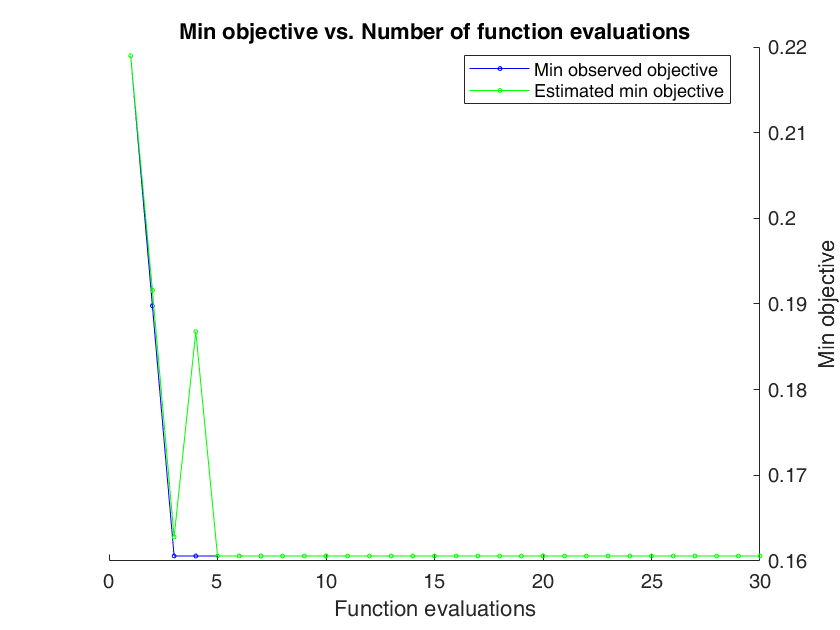

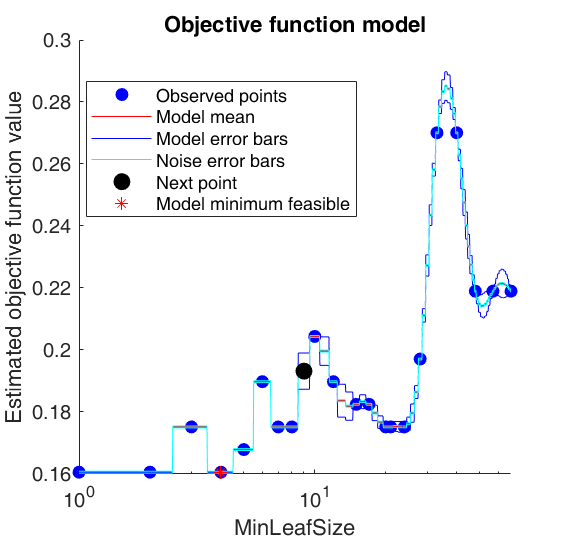

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.21898 |    0.083375 |     0.21898 |     0.21898 |           57 |
|    2 | Best   |     0.18978 |    0.093397 |     0.18978 |     0.19161 |            6 |
|    3 | Best   |     0.16058 |     0.10772 |     0.16058 |     0.16281 |            2 |
|    4 | Accept |     0.18248 |      0.1019 |     0.16058 |     0.18677 |           15 |
|    5 | Accept |     0.16058 |     0.11813 |     0.16058 |     0.16059 |            2 |
|    6 | Accept |     0.17518 |     0.13029 |     0.16058 |     0.16059 |            3 |
|    7 | Accept |     0.16058 |     0.16181 |     0.16058 |     0.16059 |            1 |
|    8 | Accept |    

model =   ClassificationTree
                       PredictorNames: {1×22 cell}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 137
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


% Find the optimum hyperparameters
model = fitctree(Xtrain,Ytrain,'OptimizeHyperparameters','auto')

% Initial Model
view(model);


Decision tree for classification
1  if PPE<0.106398 then node 2 elseif PPE>=0.106398 then node 3 else 1
2  class = 0
3  if PPE<0.184526 then node 4 elseif PPE>=0.184526 then node 5 else 1
4  if MDVP_Fo_Hz_<118.018 then node 6 elseif MDVP_Fo_Hz_>=118.018 then node 7 else 1
5  class = 1
6  class = 0
7  if MDVP_Fhi_Hz_<229.18 then node 8 elseif MDVP_Fhi_Hz_>=229.18 then node 9 else 1
8  class = 1
9  class = 0



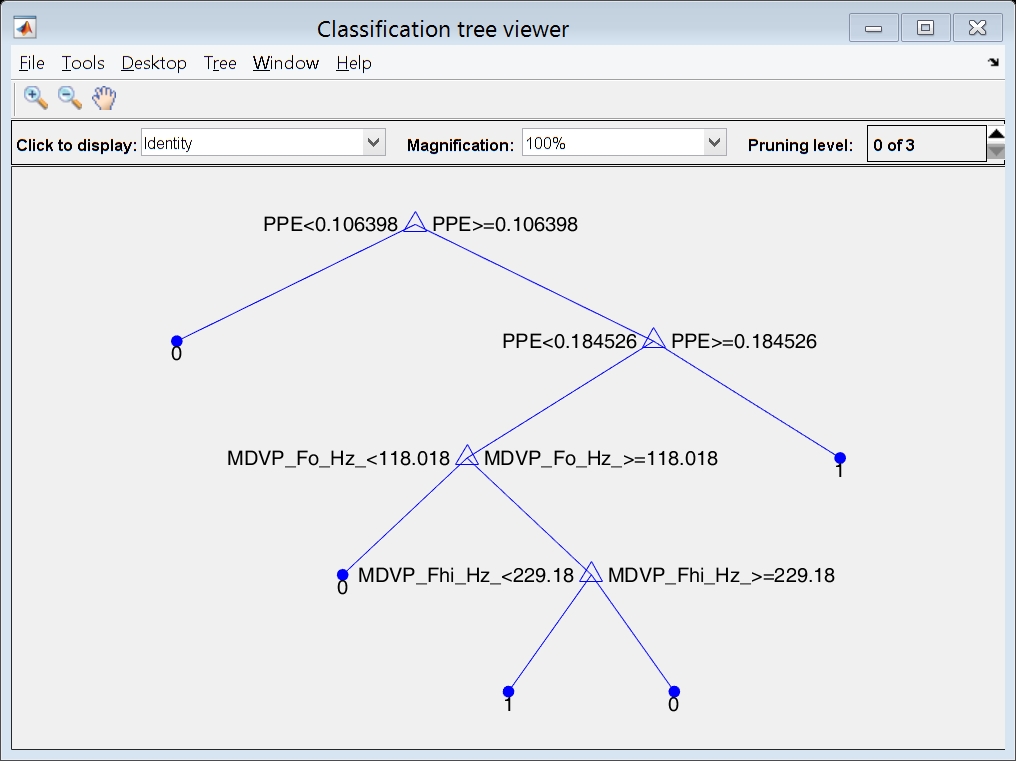

view(model,'mode','graph')


% Best Model using MinLeafSize obtained from above model
BestModel = fitctree(Xtrain,Ytrain,'MinLeafSize',model.ModelParameters.MinLeaf) 

BestModel =   ClassificationTree
           PredictorNames: {1×22 cell}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1]
           ScoreTransform: 'none'
          NumObservations: 137


  Properties, Methods


view(BestModel)


Decision tree for classification
1  if PPE<0.106398 then node 2 elseif PPE>=0.106398 then node 3 else 1
2  class = 0
3  if PPE<0.184526 then node 4 elseif PPE>=0.184526 then node 5 else 1
4  if MDVP_Fo_Hz_<118.018 then node 6 elseif MDVP_Fo_Hz_>=118.018 then node 7 else 1
5  class = 1
6  class = 0
7  if MDVP_Fhi_Hz_<229.18 then node 8 elseif MDVP_Fhi_Hz_>=229.18 then node 9 else 1
8  class = 1
9  class = 0



view(BestModel,'mode','graph')

YPred_dt = predict(BestModel,Xtest);
Accuracy_dt = sum(YPred_dt == Ytest)/length(Ytest);
Precision_dt = sum(double(YPred_dt)==1 & double(Ytest)==1)/sum(double(YPred_dt) == 1);
Recall_dt = sum(double(YPred_dt) ==1 & double(Ytest) == 1)/sum(double(Ytest) == 1);
% cross validation error for 10-fold cross validation
CVError_dt = cvloss(BestModel);
table(Accuracy_dt,Precision_dt,Recall_dt,CVError_dt)

ans = 1×4 table
    Accuracy_dt    Precision_dt    Recall_dt    CVError_dt
    ___________    ____________    _________    __________

      0.86207        0.77778        0.77778      0.14599  


confusionmat(double(Ytest), double(YPred_dt))

Class List in given sample
     1
     2


Total Instance = 58
class1==>1
class2==>2
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          14                 4      
    Actual_class2           4                36      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          14]    [            4]
    'TrueNegative=TN'    [           4]    [           36]

Over all valuses
                          Accuracy: 0.8621
                             Error: 0.1379
                       Sensitivity: 0.7778
                       Specificity: 0.9000
                         Precision: 0.7778
                 FalsePositiveRate: 0.1000
                          F1_score: 0.7778
    MatthewsCorrelationCoefficient: 0.6778
            

ans =     14     4
     4    36


**RANDOM FOREST**

% check  error based on number of trees and find MinLeafSize
RFmodel = TreeBagger(100, Xtrain, Ytrain,'OOBPrediction','On')

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [137x22]
                    Training Y:              [137x1]
                        Method:       classification
                 NumPredictors:                   22
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


err = oobError(RFmodel)

err =     0.2190
    0.1825
    0.1533
    0.1387
    0.1606
    0.1314
    0.1460
    0.1460
    0.1679
    0.1460


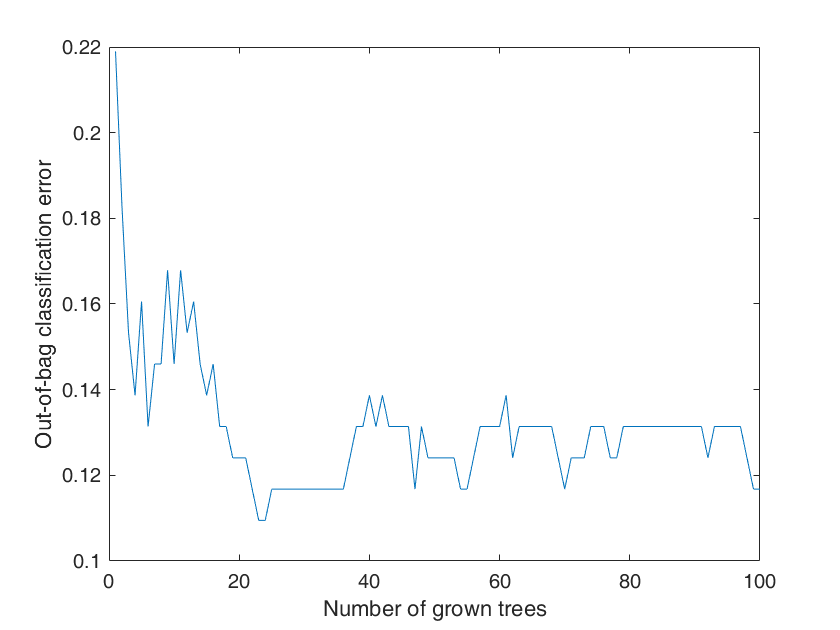

plot(err)
xlabel('Number of grown trees') ;
ylabel('Out-of-bag classification error');

% Optimized model using MinLeafSize obtained above
RFmodel = TreeBagger(100, Xtrain, Ytrain, 'MinLeafSize', RFmodel.MinLeafSize, ...
    'OOBPrediction', 'On','OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [137x22]
                    Training Y:              [137x1]
                        Method:       classification
                 NumPredictors:                   22
         NumPredictorsToSample:                    5
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


err = oobError(RFmodel) 

err =     0.2701
    0.2555
    0.2701
    0.2628
    0.2482
    0.2701
    0.2482
    0.2117
    0.1971
    0.1752


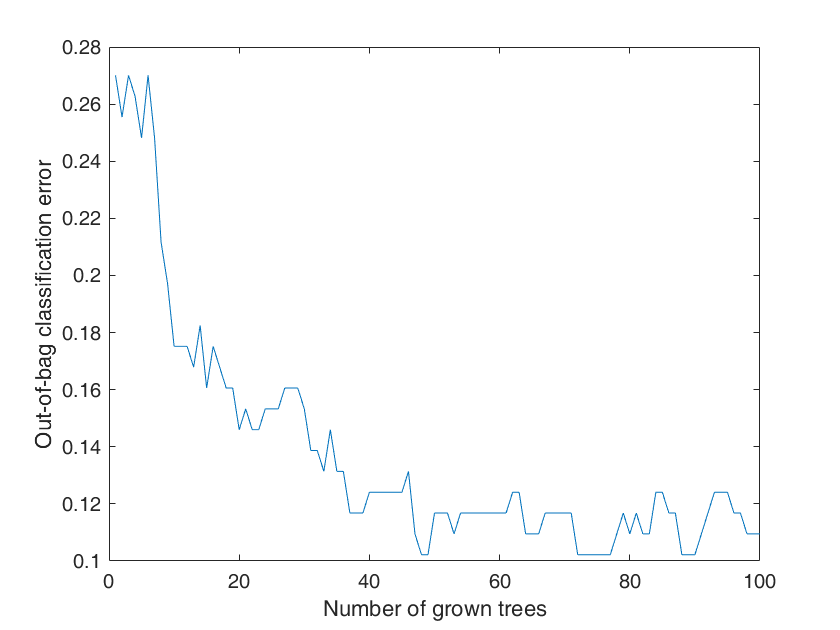

plot(err)
xlabel('Number of grown trees') ;
ylabel('Out-of-bag classification error');

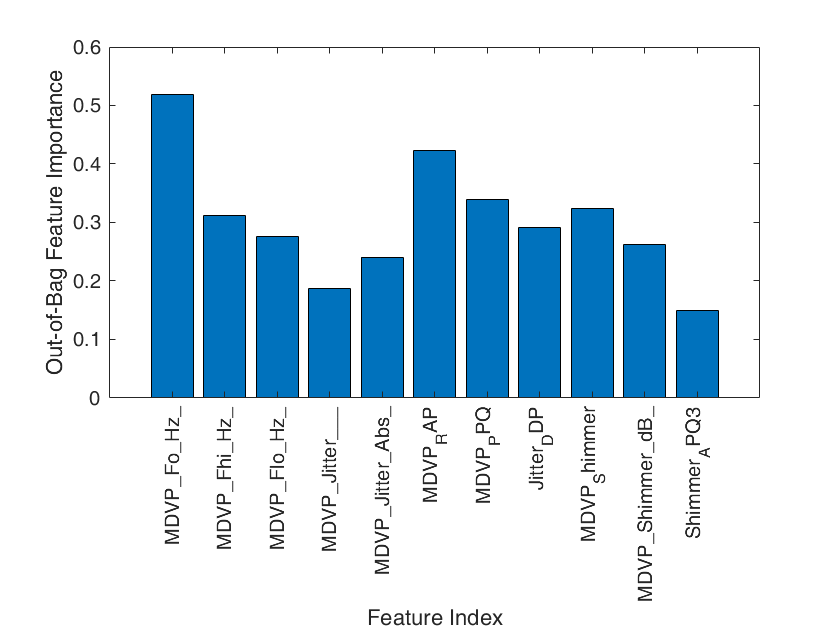

bar(RFmodel.OOBPermutedPredictorDeltaError(1:11))
xlabel('Feature Index')
ylabel('Out-of-Bag Feature Importance')
xticklabels(data_names(1:11))
xtickangle(90)

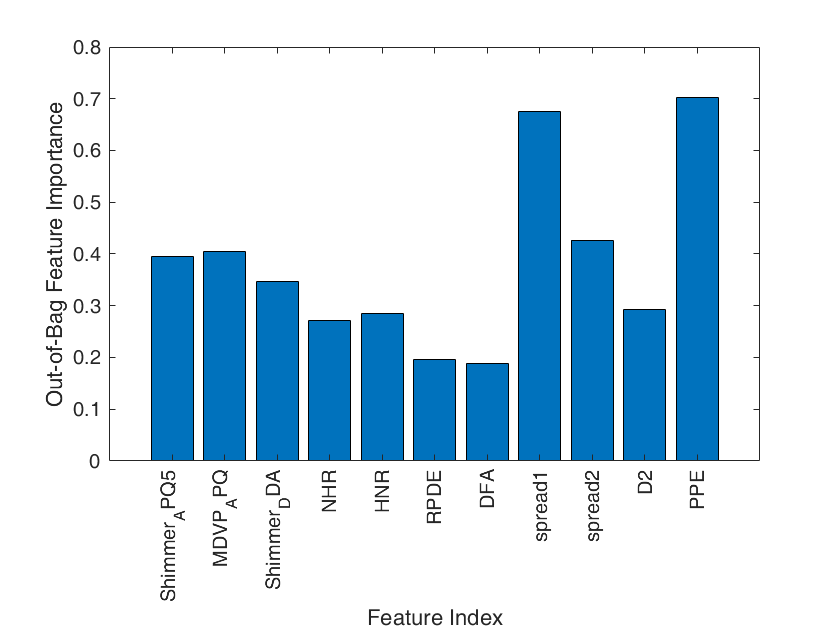

bar(RFmodel.OOBPermutedPredictorDeltaError(12:22))
xlabel('Feature Index')
ylabel('Out-of-Bag Feature Importance')
xticklabels(data_names(12:22))
xtickangle(90)

% predict in test set
YPred = predict(RFmodel,Xtest) % output is in a cell array. convert to number

YPred = 58×1 cell array
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'0'}
    {'0'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}


% convert cell to categorical
YPred = categorical(YPred)

YPred = 58×1 categorical array
     1 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     0 
     1 
     0 
     0 
     0 
     1 
     1 
     1 
     0 
     0 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


acc_RF = sum(YPred == Ytest)/length(Ytest)

acc_RF = 0.8793

confusionmat(double(Ytest), double(YPred))

Class List in given sample
     1
     2


Total Instance = 58
class1==>1
class2==>2
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          9                  2      
    Actual_class2          5                 42      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [           9]    [            2]
    'TrueNegative=TN'    [           5]    [           42]

Over all valuses
                          Accuracy: 0.8793
                             Error: 0.1207
                       Sensitivity: 0.8182
                       Specificity: 0.8936
                         Precision: 0.6429
                 FalsePositiveRate: 0.1064
                          F1_score: 0.7200
    MatthewsCorrelationCoefficient: 0.6521
            

ans =      9     2
     5    42


**SUPPORT VECTOR MACHINES**

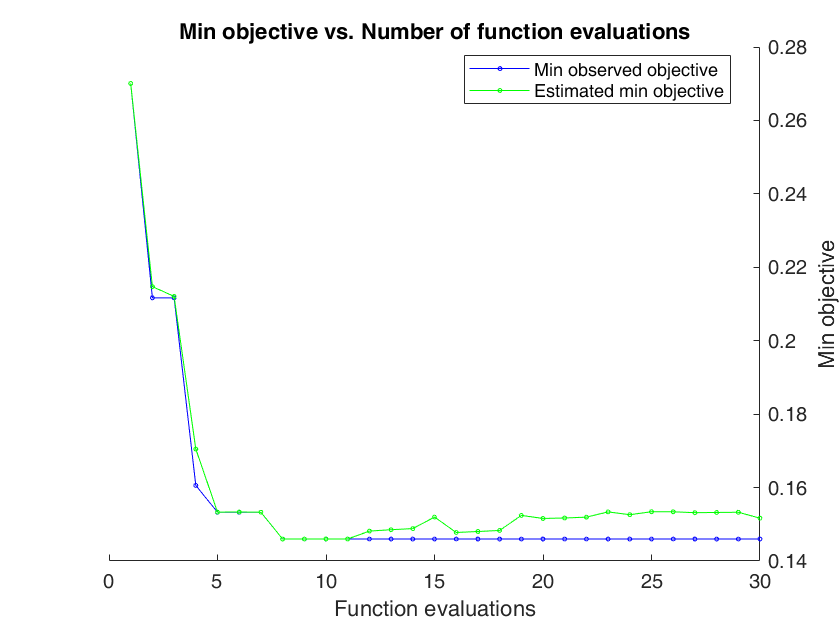

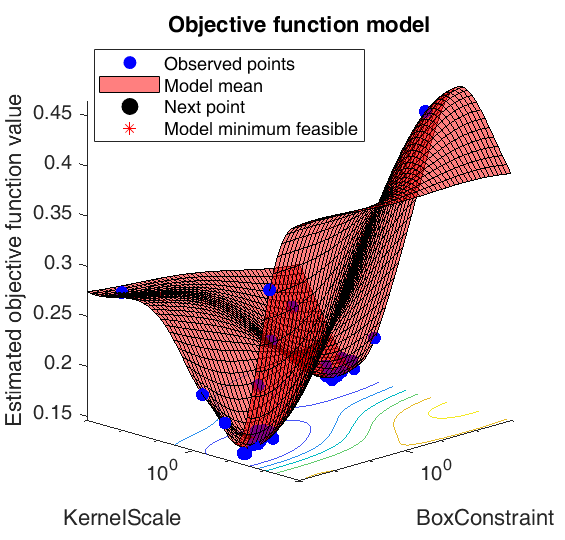

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.27007 |     0.16271 |     0.27007 |     0.27007 |    0.0046781 |       483.98 |
|    2 | Best   |     0.21168 |     0.27526 |     0.21168 |     0.21474 |       177.05 |       274.89 |
|    3 | Accept |     0.44526 |      24.729 |     0.21168 |     0.21207 |       175.17 |     0.047023 |
|    4 | Best   |     0.16058 |      15.441 |     0.16058 |      0.1705 |     0.002732 |      0.05366 |
|    5 | Best   |     0.15328 |      13.468 |     0.15328 |     0.15332 |    0.0016411 |     0.062613 |
|    6 | Accept |     0.20438 |     0.23768 |     0.15328 |     

svmmod =   ClassificationSVM
                       PredictorNames: {1×22 cell}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 137
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [58×1 double]
                                 Bias: 6.1334
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [137×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [137×1 logical]
                               Solver: 'SMO'


  Properties, Methods


% Partitioning the data for 10-fold cross validation
c = cvpartition(size(Xtrain, 1),'KFold',10);
% Finding the optimum parameters
opts = struct('Optimizer','bayesopt','ShowPlots',true,'CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');
svmmod = fitcsvm(Xtrain,Ytrain,'KernelFunction','linear','OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',opts)

% Using the optimized BoxConstraint and Kernel Scale obtained from above
loss_new = kfoldLoss(fitcsvm(Xtrain,Ytrain,'CVPartition',c,'KernelFunction','linear',...
    'BoxConstraint',svmmod.HyperparameterOptimizationResults.XAtMinObjective.BoxConstraint,...
    'KernelScale',svmmod.HyperparameterOptimizationResults.XAtMinObjective.KernelScale))

loss_new = 0.1460

[labels, scores] = predict(svmmod, Xtest);
acc = sum(labels == Ytest)/length(Ytest)

acc = 0.8793

t = table(loss_new, acc);
t.Properties.VariableNames = {'Cross Validation Error', 'SVM Accuracy'}

t = 1×2 table
    Cross Validation Error    SVM Accuracy
    ______________________    ____________

           0.14599              0.87931   


% Initialize parameters for trainTestSplit
trainingSize = 0.8; randomstate = 2;

X = data; 
Y = PD.status;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = trainTestSplit_NN(X, Y, trainingSize, randomstate);

**NEURAL NETWORK WITH LOGISTIC REGRESSION**

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; 
Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution
% Intialize variables
epoch = 500; learning_rate = 0.05; numberOfOutputNodes = 1;  % Hyperparameters
m = size(Xtrain, 1);                                         % Normalizing scale
actFnc = 'Sigmoid';                                          % Sigmoid activation function
w = randn([size(Xtrain, 2), numberOfOutputNodes]);           % Number of Xtrain features x number of responses
b = randn([size(Xtrain, 1), 1]);     

Logistic regression with forward and backward propagation

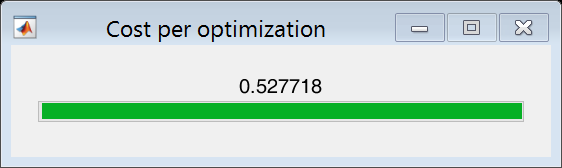

wtbr = waitbar(0, '0', 'Name', 'Cost per optimization');

for i = 1:epoch                                     % Iterate forward and backward propagation + gradient descent 500 times
    Z = Xtrain * w + b;                             % 1. Forward propagation
    ypred = activationFnc(Z, actFnc);
    
    J(i) = costFunction(Ytrain, ypred, 'Log-Loss'); % 2. Cost evaluation -> store the costs for plot
    waitbar(i/epoch, wtbr, sprintf('%f', J(i)))     %    Update the waitbar
    
    dZ = ypred - Ytrain;                            % 3. Back propagation
    dW = (1/m) .* (Xtrain' * dZ); 
    db = (1/m) .* sum(dZ, 2);
     
    w = w - (learning_rate .* dW);                  % Gradient descent for iterative update
    b = b - (learning_rate .* db);
end

Visualizing the model error from the cost curve

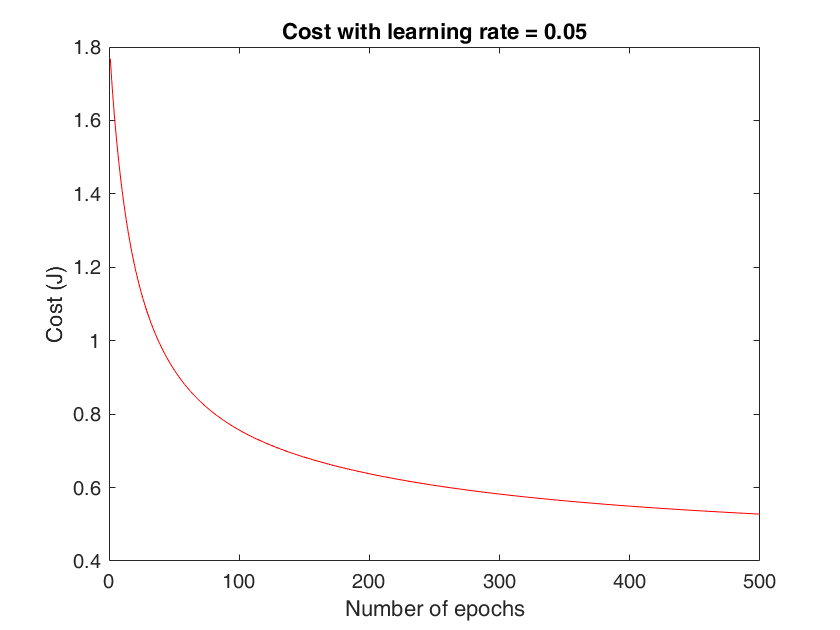

% Cost curve
figure; plot(1:epoch, J, 'color', 'r');
title('Cost with learning rate = 0.05')
xlabel('Number of epochs'); ylabel('Cost (J)')

Label encoding for classification

% Label encoding for classification
ypred(ypred >= 0.5) = 1; % If the probability is greater than 50%, set it to status1 class (people with PD)
ypred(ypred < 0.5)  = 0; % Otherwise, set it to status0 class (normal people)

Training Accuracy

% Compute training accuracy
train_accuracy = 1 - mean(ypred ~= Ytrain)

train_accuracy = 0.7500

Cross validation accuracy

kfold = 5; type = 'Logistic'; hyperparameters = {};

% Run 5 fold cross validation
logRegressCV = crossValidate_nnlr(Xtrain, Ytrain, Xtest, Ytest, ...
                            hyperparameters, kfold, type)

Class List in given sample
     0
     1


Total Instance = 32
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          6                  2      
    Actual_class2          5                 19      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [           6]    [            2]
    'TrueNegative=TN'    [           5]    [           19]

Over all valuses
                          Accuracy: 0.7813
                             Error: 0.2188
                       Sensitivity: 0.7500
                       Specificity: 0.7917
                         Precision: 0.5455
                 FalsePositiveRate: 0.2083
                          F1_score: 0.6316
    MatthewsCorrelationCoefficient: 0.4938
            

Class List in given sample
     0
     1


Total Instance = 31
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          2                  3      
    Actual_class2          1                 25      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [           2]    [            3]
    'TrueNegative=TN'    [           1]    [           25]

Over all valuses
                          Accuracy: 0.8710
                             Error: 0.1290
                       Sensitivity: 0.4000
                       Specificity: 0.9615
                         Precision: 0.6667
                 FalsePositiveRate: 0.0385
                          F1_score: 0.5000
    MatthewsCorrelationCoefficient: 0.4498
            

logRegressCV = struct with fields:
                   cm: [2×2 double]
         NormalizedCM: [2×2 double]
    Status1_precision: 0.7500
    Status0_precision: 0.9355
       Status1_recall: 0.7500
       Status0_recall: 0.9355
     average_accuracy: 0.8974


**Cross validation confusion matrix**

cm = logRegressCV.cm;
TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
Status1_precision = (TP) / (TP + FP)

Status1_precision = 0.7500

Status1_recall = (TP) / (TP + FN)

Status1_recall = 0.7500

Status0_precision = (TN) / (TN + FP)

Status0_precision = 0.9355

Status0_recall = (TN) / (TN + FN)

Status0_recall = 0.9355

average_accuracy = sum(diag(cm)) / sum(sum(cm))

average_accuracy = 0.8974

% Display model evaluation parameters
% Status0 - Normal People (without PD)
% Status1 - People with PD
t = table(Status0_recall, Status1_recall, Status0_precision, Status1_precision, average_accuracy);
t.Properties.VariableNames = {'WithoutPD_recall', 'WithPD_recall', 'WithoutPD_precision', 'WithPD_precision', 'Average Accuracy'}

t = 1×5 table
    WithoutPD_recall    WithPD_recall    WithoutPD_precision    WithPD_precision    Average Accuracy
    ________________    _____________    ___________________    ________________    ________________

        0.93548             0.75               0.93548                0.75              0.89744     


**SHALLOW NEURAL NETWORK**

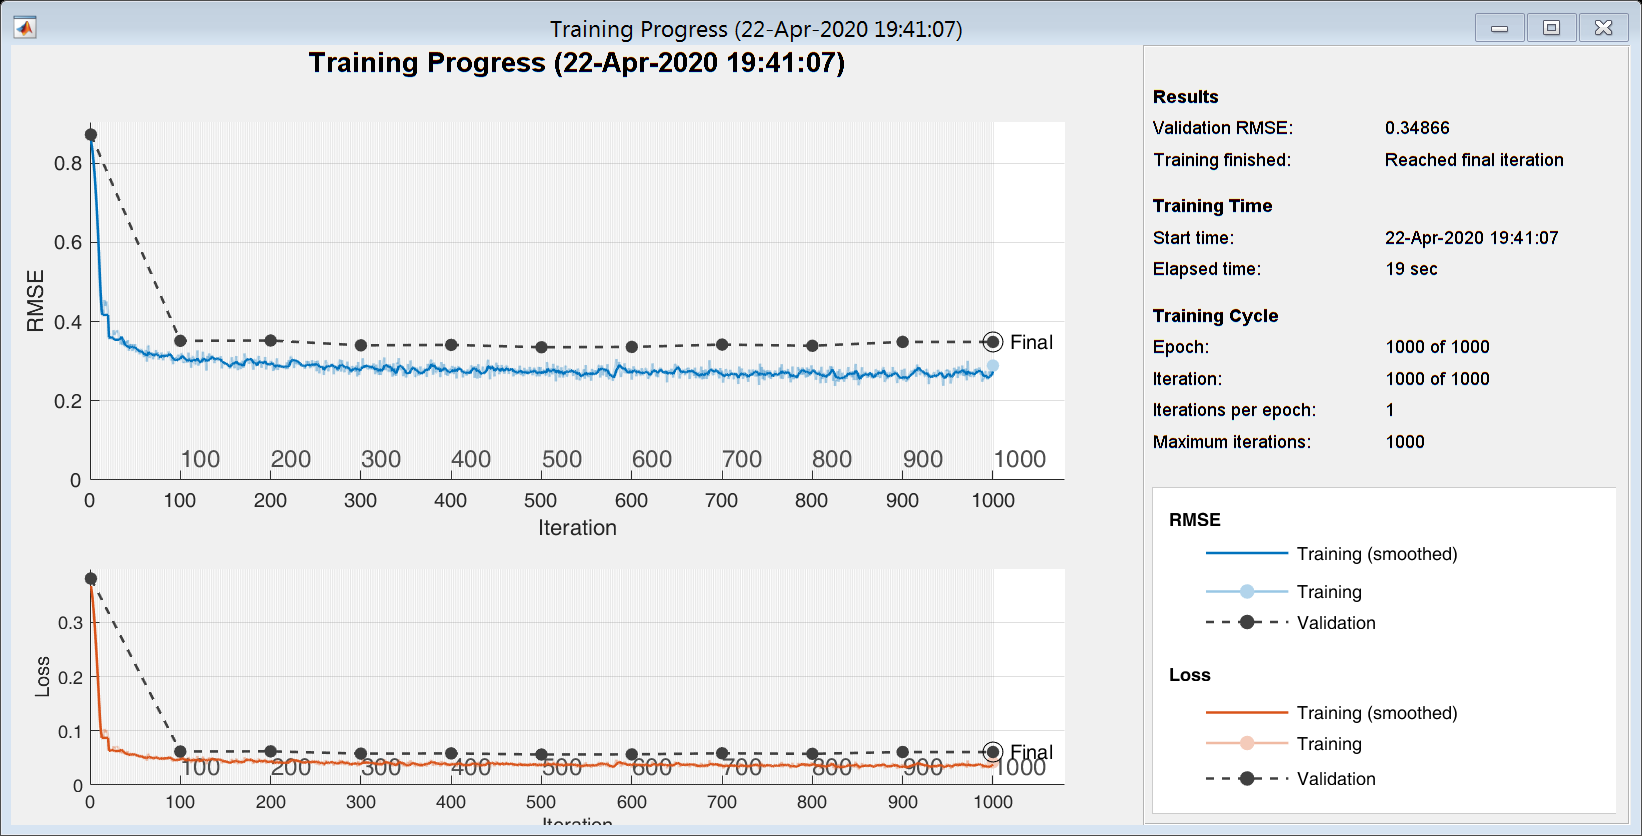

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |         0.86 |         0.87 |       0.3671 |       0.3806 |          0.0100 |
|      50 |          50 |       00:00:01 |         0.34 |              |       0.0589 |              |          0.0100 |
|     100 |         100 |       00:00:02 |         0.31 |         0.35 |       0.0472 |       0.0618 |          0.0100 |
|     150 |         150 |       00:00:03 |         0.29 |              |       0.0424 |              |          0.0100 |
|     20

snn =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'regressionoutput'}


Xtrain = zscore(Xtrain);
Xtest = zscore(Xtest);
Xtrain = Xtrain'; 
Ytrain = Ytrain'; 
Xtest = Xtest'; 
Ytest = Ytest';

% Neural Networks for Regression
% Shallow Neural Network Architecture
snnlayers = [...
    
    sequenceInputLayer(size(Xtrain, 1))           % Input data layer
    
    fullyConnectedLayer(10, ...                   % Hidden layer 1 with 10 activation nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal') 
    
    dropoutLayer(0.3)                             % Randomly and temporarily drop out 30% of the data
    reluLayer                                     % ReLU activation function 
    
    fullyConnectedLayer(size(Ytrain, 1), ...      % Output layer with 1 nodes corresponding to age vector
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal') 
    
    regressionLayer                               % Regression layer
];

options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 1000, ...                        % Maximum number of epochs to train algorithm
    'ValidationData', {Xtest, Ytest}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 100, ...               % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'L2Regularization', 1.0000e-05, ...           % Perform additional Ridge Regularization to constrain the model further
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
); 

[snn, ~] = trainNetwork(Xtrain, Ytrain, snnlayers, options)

ypred_snn = predict(snn, Xtest)

ypred_snn = 1×39 single row vector
    1.2073    0.5460    1.1841    1.0224    0.2705    0.8084    0.2982    0.4862    0.8869    0.4243    0.2720    0.3814    0.3476    1.2253    0.2675    1.1153    0.6803    1.0797    1.1633    1.0959    0.7828    0.9952    1.0203    0.3806    0.5285    1.2372    0.2479    0.5087    0.6257    1.1065    1.0729    1.0717    0.8651    0.9391    0.7516    0.9126    0.3622    0.4236    0.3385


% Approximation
% If ypred_sunn < 0.5 it is rounded to 0 and assigned Status0 and if
% ypred_snn > 0.5 it is rounded to 1 and assigned Status1
for i = 1:length(ypred_snn)
    if ypred_snn(i) < 0.5
        ypred_snn(i) = 0;
    else
        ypred_snn(i) = 1;
    end
end

% Correlation
r_snn = corr(Ytest', ypred_snn')

r_snn = single
0.7184

% Accuracy
acc_snn = sum(ypred_snn == Ytest)/length(Ytest)

acc_snn = 0.8718


t1 = table(r_snn, acc_snn);
t1.Properties.VariableNames = {'Correlation', 'Accuracy'}

t1 = 1×2 table
    Correlation    Accuracy
    ___________    ________

      0.71842      0.87179 


**RESULTS TABLE:**

res_table = table(mean_accuracy_randomGuess,avg_accuracy_log_reg,Accuracy_dt, acc_RF, acc, average_accuracy, acc_snn);
res_table.Properties.VariableNames = {'Random Guess', 'Logistic Regression', 'Decision Trees', 'Random Forest', 'SVM', 'Neural Network with Logistic Regression', 'Shallow Neural Network'}

res_table = 1×7 table
    Random Guess    Logistic Regression    Decision Trees    Random Forest     SVM      Neural Network with Logistic Regression    Shallow Neural Network
    ____________    ___________________    ______________    _____________    ______    _______________________________________    ______________________

       0.6379             0.8401               0.8621           0.8793        0.8793                    0.8974                             0.8718        
